$f(x_i) = \left(1 +\frac{1}{n}\right)^2$**Name: Boahen Papa Kofi**

**Roll Number: 10211100334**

**Course: BSc Computer Engineering**

**Question 1 **

Evaluating the one-sided limits

syms x
fprintf("Question 1")

Question 1

% disp("Let f and g represent the different functions of the piecewise-defined function")
f(x) = piecewise(x<0, x + 3, x>=0, -x + 3) 

$$f(x) = \left\{ \begin{array}{cl} x+3 & \text{ if }x<0\\ 3-x & \text{ if }0\leq x \end{array}\right.$$


% Right-hand limit
Rhlimit1 = limit(f(x),x,0,"right")

$$Rhlimit1 = 3$$


% Left-hand limit
Lhlimit1 = limit(f(x),x,0,"left")

$$Lhlimit1 = 3$$


% Two-sided limit
limit1 =limit(f(x),x,0)

$$limit1 = 3$$




if (Lhlimit1 == Rhlimit1) %if the one-sided limits are equal
   fprintf("Two sided limit of f(x) exists equal to %d\n.", Rhlimit1)
else
    fprintf("Two sided limit of f(x) fails to exist \n since the left-hand limit = %d is not equal to the right-hand limit = %d", Lhlimit2,Rhlimit2)
end

Two sided limit of f(x) exists equal to 3
.


% Plot the function
disp("The figure below shows the graph of f(x)")

The figure below shows the graph of f(x)


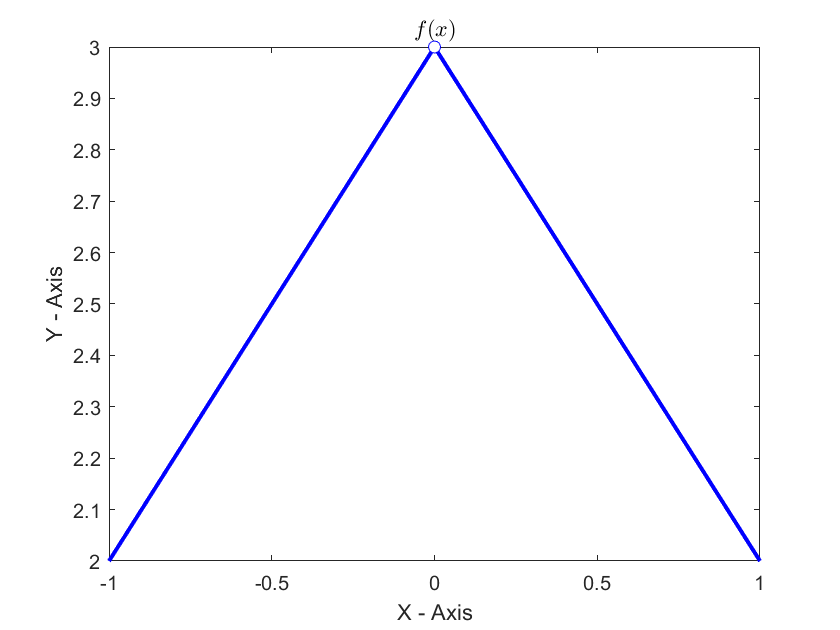

fplot(f(x), [-1,1], "Color","blue", "LineWidth", 2)
hold on
plot(0,3,'bo',"Color",'b','MarkerFaceColor','w')
xlabel("X - Axis")
ylabel("Y - Axis")
value = "$f(x)$";
title(value, "Interpreter", "latex")
hold off

% set(gca,'XAxisLocation', 'origin', 'YAxisLocation','origin')


Finally we conclude ,  since $\lim_{x\to0^-} (x+3)  = 3$ and $\lim_{x\to0^+} (-x+3) =  3$ then 

$\lim_{x \to 0} f(x) = 3$** exists.**


$$where \quad f(x) = \begin{cases} 
		x + 3, \ & x < 0 \\
		-x + 3, \ & x \geq 0 
	\end{cases}$$


**Question 2**

Evaluating the one- sided limits

disp("Question 2")

Question 2



g(x) = piecewise(x<2, x, x>=2, x + 1)

$$g(x) = \left\{ \begin{array}{cl} x & \text{ if }x<2\\ x+1 & \text{ if }2\leq x \end{array}\right.$$


%Left-hand limit
Lhlimit2 = limit(g(x), x, 2, "left")

$$Lhlimit2 = 2$$


%Right-hand limit
Rhlimit2 = limit(g(x), x, 2, "right")

$$Rhlimit2 = 3$$



if (Lhlimit2 == Rhlimit2) %if the one-sided limits are equal
   fprintf("Two sided limit of f(x) exists equal to %d\n.", Rhlimit2)
else
    fprintf("Two sided limit of f(x) fails to exist \n since the left-hand limit = %d is not equal to the right-hand limit = %d", Lhlimit2,Rhlimit2)
end

Two sided limit of f(x) fails to exist 
 since the left-hand limit = 2 is not equal to the right-hand limit = 3


% Plot the function
disp("The figure below shows the graph of g(x)")

The figure below shows the graph of g(x)


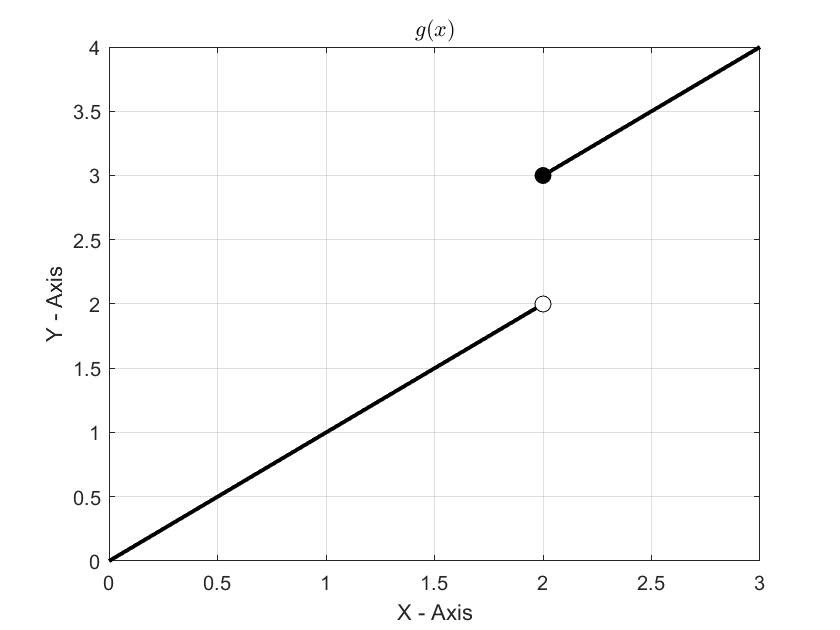

fplot(g(x), [0 1.9999],'-', "Color","#000000", "LineWidth", 2)
grid on; hold on
fplot(g(x), [2.0001 3], '-', "Color","#000000", "LineWidth", 2)
plot(2 , 2,'ko',"MarkerFaceColor","w","MarkerSize",8)
plot(2,3,'ko',"MarkerFaceColor","k","MarkerSize",8)
xlabel("X - Axis")
ylabel("Y - Axis")
title("$g(x)$", "Interpreter", "latex")
hold off

fig1 = figure;
ax1 = axes(fig1);
ax1.XAxisLocation = 'top';
ax1.YAxisLocation = 'origin';

Finally, we conclude, since $\lim_{x\to2^-} (x) =  2 $ and $\lim_{x\to2^+} (x+1) =  3$ , the left-hand limit and the right hand-limit are not equal

$\therefore \ \lim_{x \to 2} g(x) $ **fails to exist.**


$$ where \quad g(x) = \begin{cases} 
		x, \ &x < 2 \\
		x + 1, \ &x \geq 2 
	\end{cases}$$


**Question 3**

Evaluating the one-sided limits

disp("Question 3")

Question 3



h(x) = piecewise(x<2, x^2 - 2*x,x>2, x^2-6*x+8, 1)

$$h(x) = \left\{ \begin{array}{cl} x^{2}-2\,x & \text{ if }x<2\\ x^{2}-6\,x+8 & \text{ if }2<x\\ 1 & \mathrm{otherwise} \end{array}\right.$$



%Left-hand limit
Lhlimit3 = limit(h(x), x, 2, "left")

$$Lhlimit3 = 0$$


%Right-hand limit
Rhlimit3 = limit(h(x), x, 2, "right")

$$Rhlimit3 = 0$$


if (Lhlimit3 == Rhlimit3)
    fprintf("Two sided limit of f(x) exists equal to %d", Rhlimit3)
else
    disp("Two sided limit of f(x) fails to exist")
    disp("since the left-hand limit")
    disp(Lhlimit3), disp("is not equal to the right-hand limit"), disp(Rhlimit3)
end

Two sided limit of f(x) exists equal to 0


% Plot the function
disp("The figure below shows the graph of g(x)")

The figure below shows the graph of g(x)


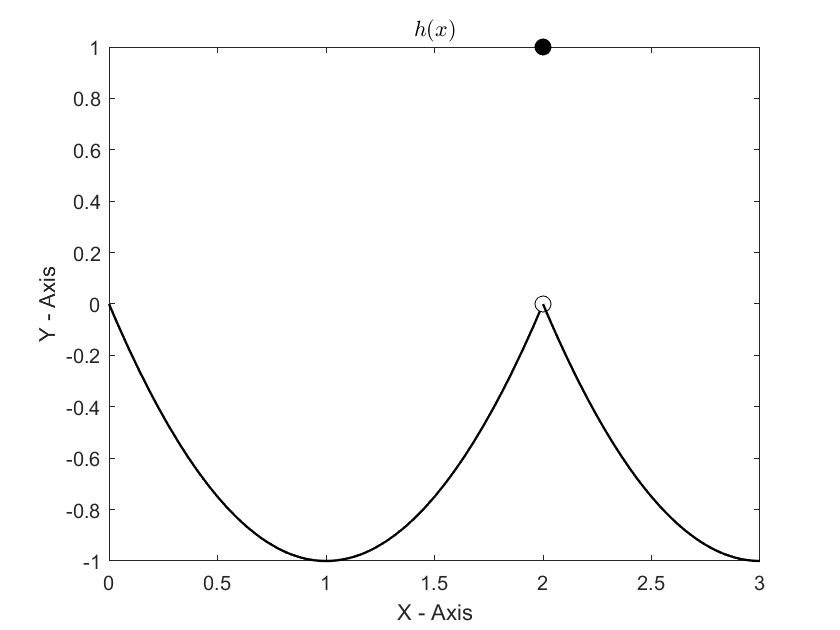

fplot(h(x), [0,1.9999], "Color","black", "LineWidth", 1.2)
hold on
plot(2,1,'ko','MarkerFaceColor','k','MarkerSize', 8)
plot(2,0,'ko','MarkerFaceColor','w','MarkerSize', 8)
fplot(h(x),[2.00001 3], "Color", 'black', 'LineWidth', 1.2)
xlabel("X - Axis")
ylabel("Y - Axis")
title("$h(x)$","Interpreter", "latex")
current_axes = gca;
current_axes.TitleHorizontalAlignment = 'center';
axis auto

Finally, we conclude, since $\lim_{x\to2^-} (x^2 - 2x) = 0$ and $\lim_{x\to2^+} (x^2 -6x + 8) = 0$ then 

$\lim_{x \to 2} h(x) = 0 $    **exists.**


$$where \quad h(x) = \begin{cases} 
	x^{2} - 2x, \ & x < 2 \\
	1, \ & x = 2 \\
	x^{2} - 6x + 8, \ & x > 2 
\end{cases}$$
